7. Let $u\left(x\right)=\frac{1}{x+1}$ on [0,2]. Approximate u on [0,2] using n equally spaced subintervals for n=2,5,10 using.

a) n cubic splines with the polynomial approach

b) n cubic splines with B-spline approach

c) n cubic using the spline command in matlab.

Plot your results and compare to those from H1. How do your results change if you use a 'natural' spline or a 'clamped' spline.

a)

We will use the same method with problem 5.

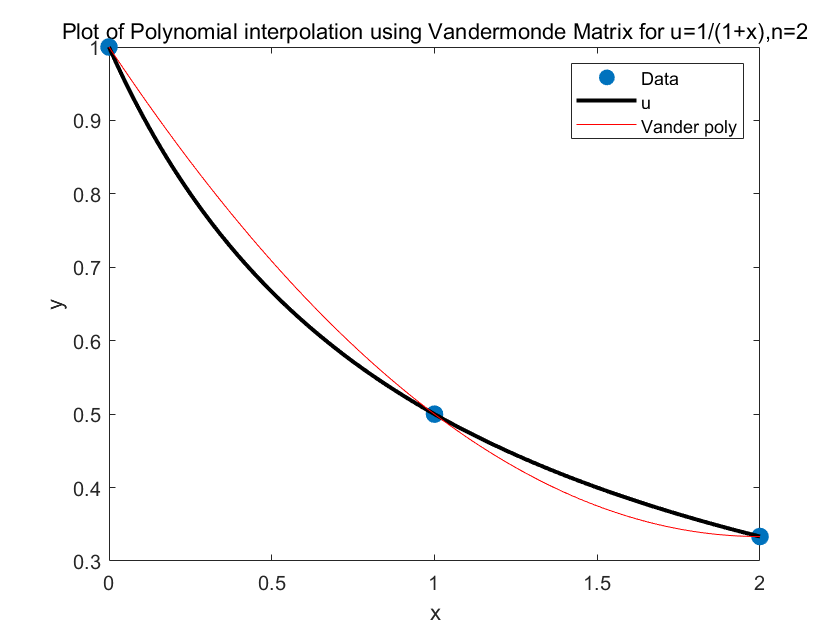

clear
a=0;
b=2;
x=a:0.01:b;
ut=u(x);%real

%a)
%Vandermonde matrix
n = 2; % number of intervals
[x2V,y2V,xfine2V,u_Vander_fine2V,a_vec2V]=van(a,b,n);
plotA(x2V,y2V,xfine2V,u_Vander_fine2V,n)

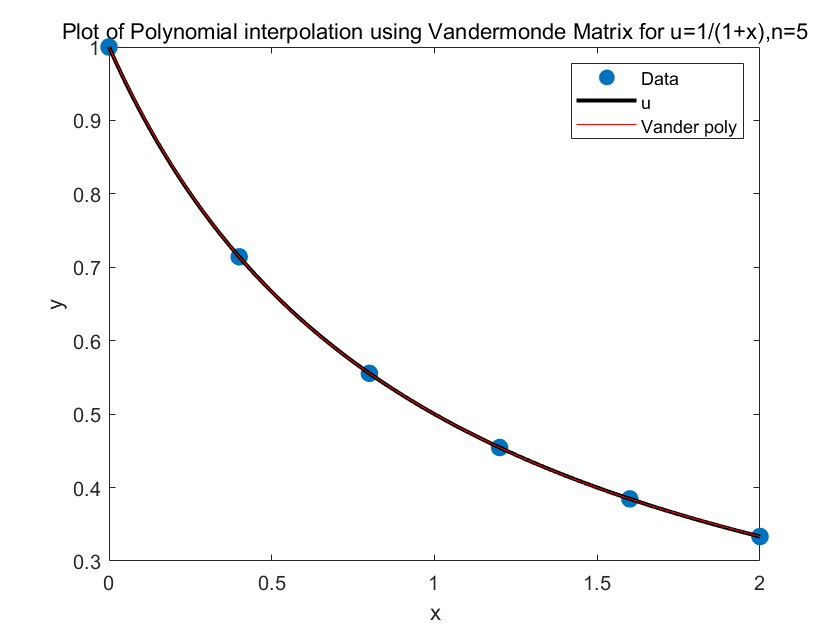


n = 5; % number of intervals
[x5V,y5V,xfine5V,u_Vander_fine5V,a_vec5V]=van(a,b,n);
plotA(x5V,y5V,xfine5V,u_Vander_fine5V,n)

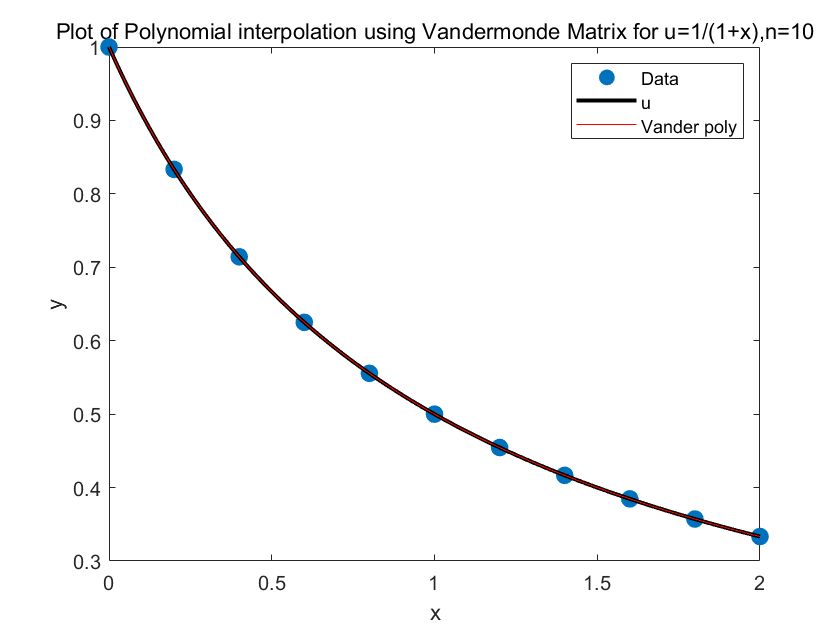


n = 10; % number of intervals
[x10V,y10V,xfine10V,u_Vander_fine10V,a_vec10V]=van(a,b,n);
plotA(x10V,y10V,xfine10V,u_Vander_fine10V,n)

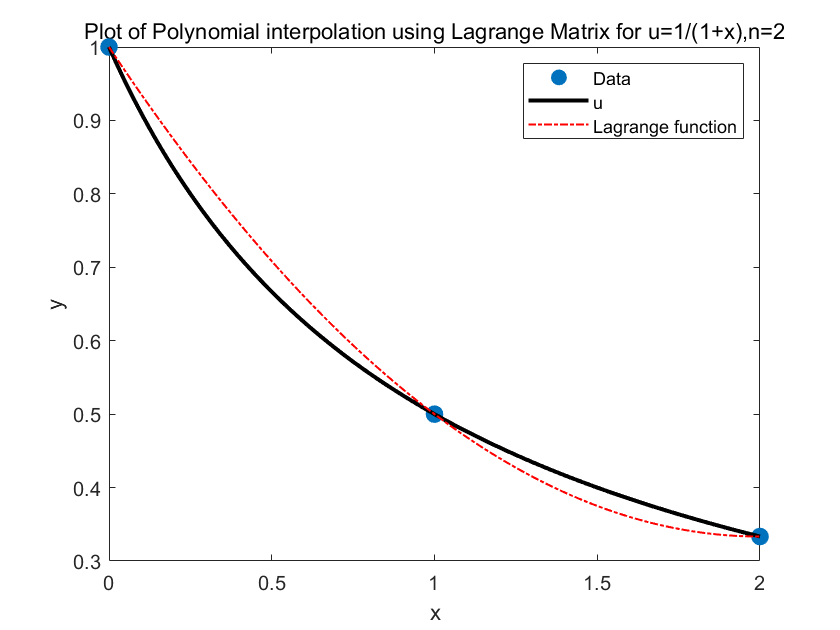


%Lagrange fomular
n = 2; % number of intervals
[x2L,y2L,xfine2L,u_Lagrange2L]=lan(a,b,n);
plotAN(x2L,y2L,xfine2L,u_Lagrange2L,n)

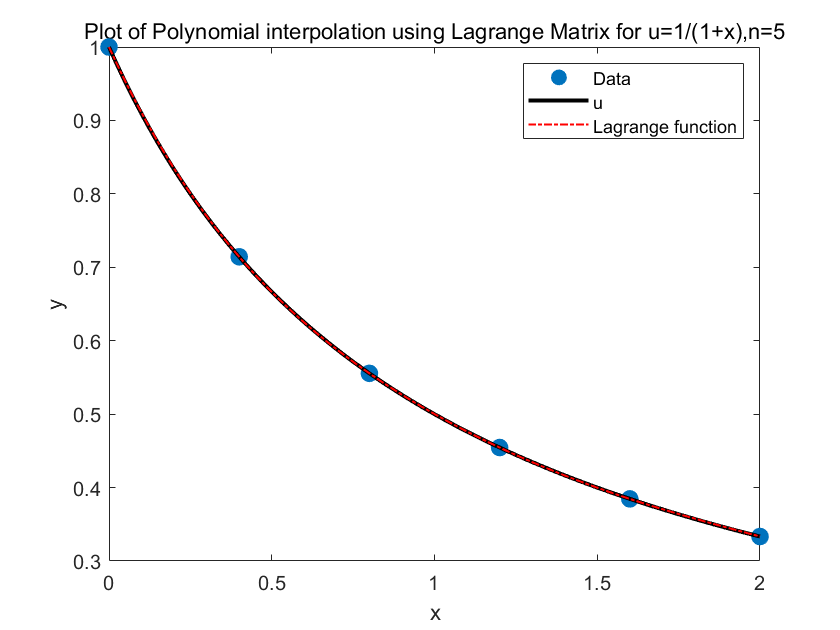


n = 5; % number of intervals
[x5L,y5L,xfine5L,u_Lagrange5L]=lan(a,b,n);
plotAN(x5L,y5L,xfine5L,u_Lagrange5L,n)

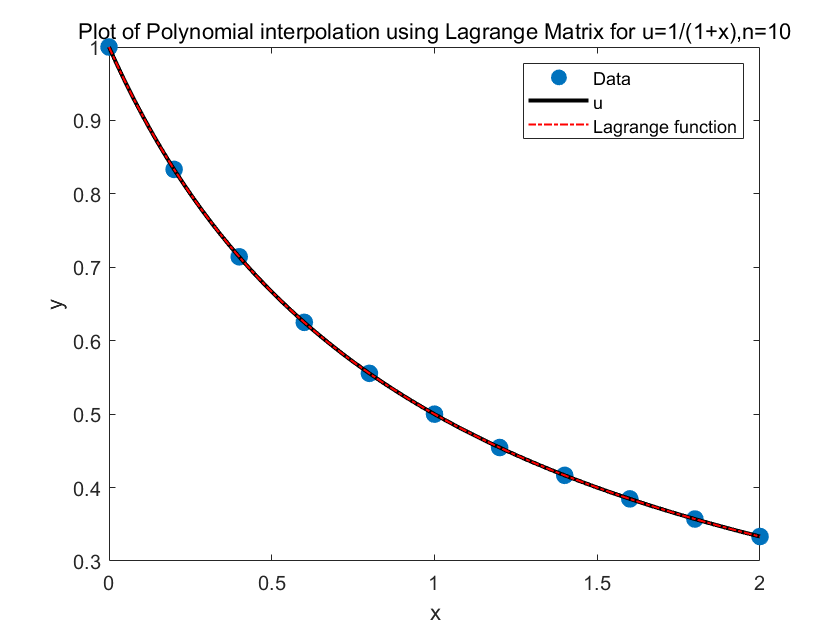


n = 10; % number of intervals
[x10L,y10L,xfine10L,u_Lagrange10L]=lan(a,b,n);
plotAN(x10L,y10L,xfine10L,u_Lagrange10L,n)

b)

With B-spline approach

In B-spline method we will use multiple B function


$$B\left(t\right)=\left\lbrace \begin{array}{cc}
\frac{1}{6}t^3  & 0\le t\le 1\\
\frac{1}{6}\left\lbrack -3{\left(t-1\right)}^3 +3{\left(t-1\right)}^2 +3\left(t-1\right)+1\right\rbrack  & 1\le t\le 2\\
\frac{1}{6}\left\lbrack 3{\left(t-2\right)}^3 -6{\left(t-2\right)}^2 +4\right\rbrack  & 2\le t\le 3\\
\frac{1}{6}\left\lbrack -{\left(t-3\right)}^3 +3{\left(t-3\right)}^2 -3\left(t-3\right)+1\right\rbrack  & 3\le t\le 4\\
0 & t\le 0\;\textrm{or}\;t\ge 4
\end{array}\right.$$
        
$$\begin{array}{l}
\left(13\right)\\
\\
\left(14\right)\\
\\
\left(15\right)\\
\\
\left(16\right)\\

\end{array}$$


For each B function $B_0$,$B_1$,..$B_n$, 

Each of $B_j$are shifted by h with other function

The $B_0$ ends at a+h

And $B_n$ starts at b-h

B function has length=4

So $B_0$ starts at a+h-4

And $B_n$ end at b-h+4

So if we graph it

For example n=5,a=0 and b=2


$$h=\frac{\left(b-a\right)}{n}=\frac{2}{5}=0\ldotp 4$$


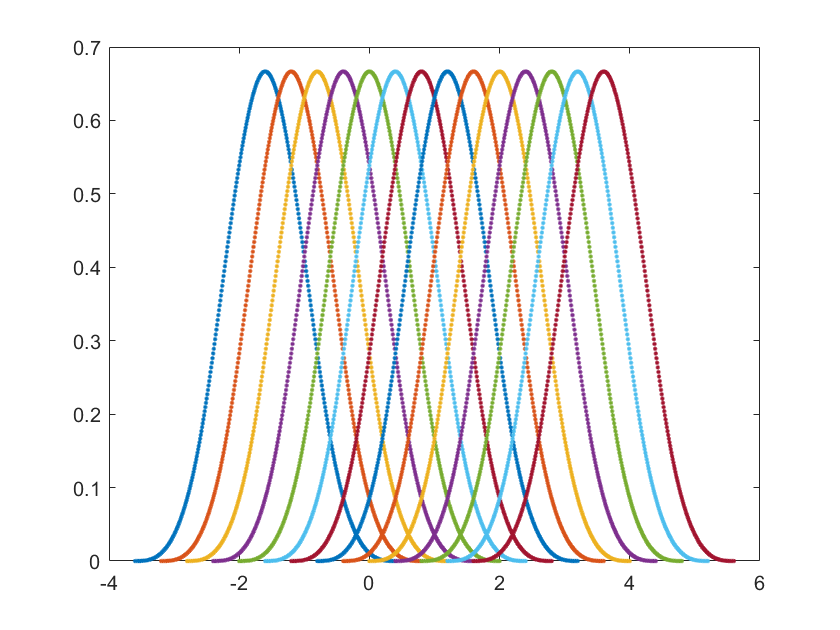

So in total, the number of B funtion will be


$$n_b =\frac{\left(b-h\right)-\left(a+h-4\right)}{h}+1=\frac{2-0\ldotp 4-0-0\ldotp 4+4}{0\ldotp 4}+1=\frac{5\ldotp 2}{0\ldotp 4}+1=14$$


$n_b =\frac{\left(b-h\right)-\left(a+h-4\right)}{h}+1$        (17)

The linear combination of B functions are:

$s\left(x\right)=\sum_j^{n_b } \alpha_j B_j$                (18)

So for $j=0,1,2,\ldotp \ldotp \ldotp ,n_b$

$u\left(0+\mathrm{ih}\right)=\sum_j^{n_b } \alpha_j B_j \left(0+\mathrm{ih}\right)$            (19)

for i=0,1,2,...n+1

And we also have

$u^{\prime } \left(a\right)=\sum_j^{n_b } \alpha_j {B^{\prime } }_j \left(a\right)$                (20)

and

$u^{\prime } \left(b\right)=\sum_j^{n_b } \alpha_j {B^{\prime } }_j \left(b\right)$                (21)

we could compute the ${B^{\prime } }_j$ first


$$B^{\prime } \left(t\right)=\left\lbrace \begin{array}{cc}
\frac{1}{2}t^2  & 0\le t\le 1\\
\frac{1}{6}\left\lbrack -9{\left(t-1\right)}^2 +6\left(t-1\right)+3\right\rbrack  & 1\le t\le 2\\
\frac{1}{6}\left\lbrack 9{\left(t-2\right)}^2 -12\left(t-2\right)\right\rbrack  & 2\le t\le 3\\
\frac{1}{6}\left\lbrack -{3\left(t-3\right)}^2 +6\left(t-3\right)-3\right\rbrack  & 3\le t\le 4\\
0 & t\le 0\;\mathrm{or}\;t\ge 4
\end{array}\right.$$
    
$$\begin{array}{l}
\left(22\right)\\
\\
\left(23\right)\\
\\
\left(24\right)\\
\\
\left(25\right)\\

\end{array}$$


therefore we can write it as matrix


$$\left\lbrack \begin{array}{cccc}
B_0 \left(0+\mathrm{0h}\right) & B_1 \left(0+0h\right) & \cdots  & B_{n_b } \left(0+0h\right)\\
B_0 \left(0+1h\right) & B_1 \left(0+1h\right) & \cdots  & B_{n_b } \left(0+1h\right)\\
\vdots  & \vdots  & \ddots  & \vdots \\
B_j \left(0+\left(n+1\right)h\right) & B_j \left(0+\left(n+1\right)h\right) & \cdots  & B_j \left(0+\left(n+1\right)h\right)\\
{B^{\prime } }_0 \left(a\right) & {B^{\prime } }_1 \left(a\right) & \cdots  & {B^{\prime } }_{n_b } \left(a\right)\\
{B^{\prime } }_0 \left(b\right) & {B^{\prime } }_1 \left(b\right) & \cdots  & {B^{\prime } }_{n_b } \left(b\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\alpha_0 \\
\alpha_1 \\
\alpha_2 \\
\vdots \\
\alpha_{n_b } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
u\left(0+0h\right)\\
u\left(0+1h\right)\\
\vdots \\
u\left(0+\left(n+1\right)h\right)\\
u^{\prime } \left(a\right)\\
u^{\prime } \left(b\right)
\end{array}\right\rbrack$$


Then we could compute $\alpha$ vector and approch the true value by using equation (18)

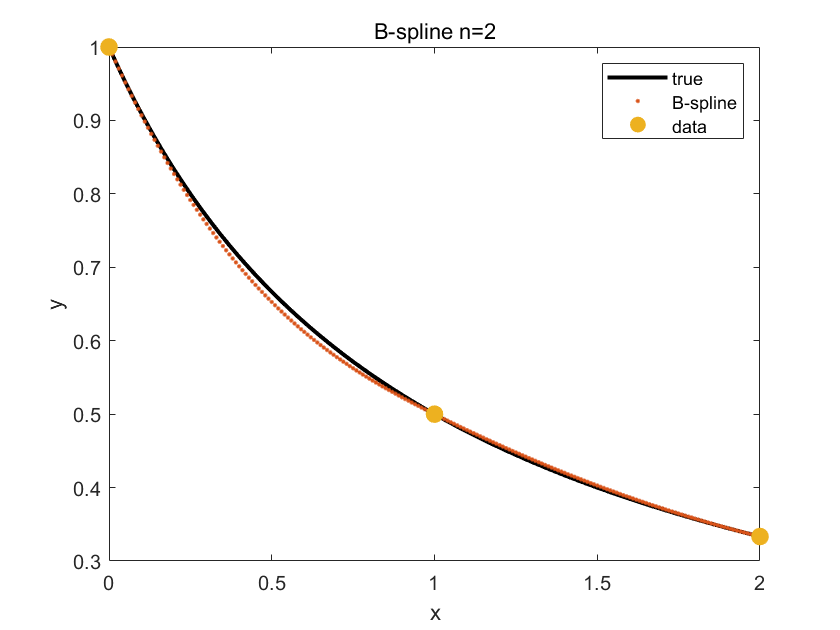

n=2;
[bc2,vv2,v2,t2]=b_clam(a,b,n);
[Y2B]=plotB(bc2,vv2,v2,x,ut,n,t2);

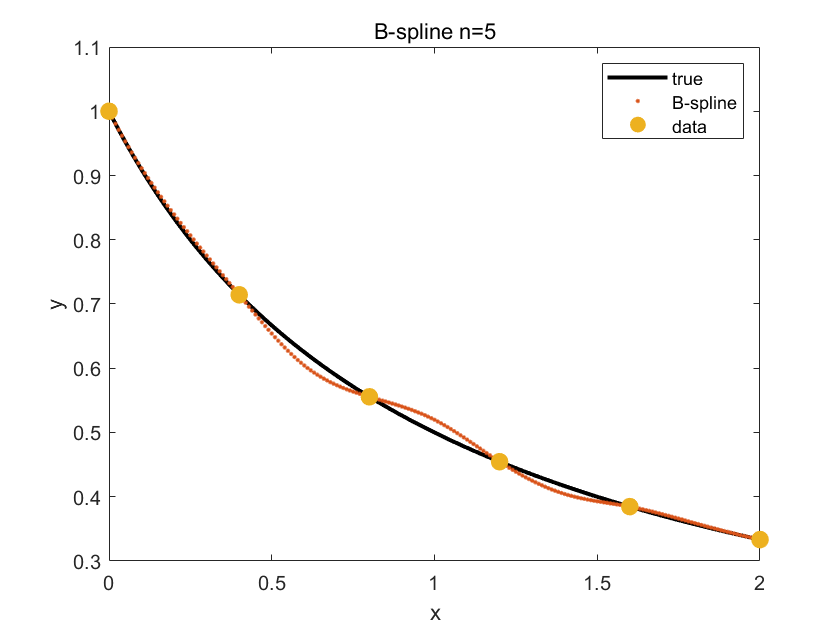


n=5;
[bc5,vv5,v5,t5]=b_clam(a,b,n);
[Y5B]=plotB(bc5,vv5,v5,x,ut,n,t5);

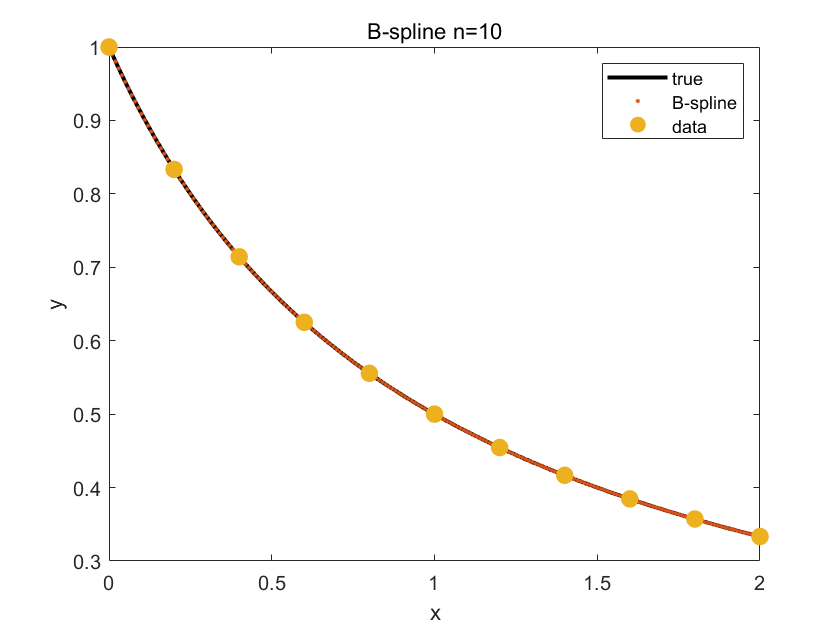


n=10;
[bc10,vv10,v10,t10]=b_clam(a,b,n);
[Y10B]=plotB(bc10,vv10,v10,x,ut,n,t10);

c)

Using clamped-spline

We will cut the function according to the numbers of data

So we define the funtion for n given data:


$$s=s\left(x\right)=\left\lbrace \begin{array}{cc}
P_1 \left(x\right) & x\in \left\lbrack x_0 ,x_1 \right\rbrack \\
P_2 \left(x\right) & x\in \left\lbrack x_1 ,x_2 \right\rbrack \\
\vdots  & \vdots \\
P_n \left(x\right) & x\in \left\lbrack x_{n-1} ,x_n \right\rbrack 
\end{array}\right.$$


And each one could be written as

$P_j \left(x\right)=a_j +b_j x+c_j x^2 +d_j x^3$            (26)

Therefore we will get the equation below

$\begin{array}{l}
P_1 \left(x_0 \right)=u\left(x_0 \right)\\
P_2 \left(x_1 \right)=u\left(x_1 \right)\\
\vdots \\
P_n \left(x_{n-1} \right)=u\left(x_{n-1} \right)
\end{array}$   (27a) and

$\begin{array}{l}
P_1 \left(x_1 \right)=u\left(x_1 \right)\\
P_2 \left(x_2 \right)=u\left(x_2 \right)\\
\vdots \\
P_n \left(x_n \right)=u\left(x_n \right)
\end{array}$            (27b)

Since we also need the first derivative to be equall

$\begin{array}{l}
{P^{\prime } }_1 \left(x_1 \right)={P^{\prime } }_2 \left(x_1 \right)\\
{P_2 }^{\prime } \left(x_2 \right)={P_3 }^{\prime } \left(x_2 \right)\\
\vdots \\
{P_{n-1} }^{\prime } \left(x_{n-1} \right)={P_n }^{\prime } \left(x_{n-1} \right)
\end{array}$                                (28)

Since we also need the second derivative to be equall

$\begin{array}{l}
{{P^{\prime } }^{\prime } }_1 \left(x_1 \right)={{P^{\prime } }^{\prime } }_2 \left(x_1 \right)\\
{P_2 }^{\prime \prime } \left(x_2 \right)={P_3 }^{\prime \prime } \left(x_2 \right)\\
\vdots \\
{P_{n-1} }^{\prime \prime } \left(x_{n-1} \right)={{P_n }^{\prime } }^{\prime } \left(x_{n-1} \right)
\end{array}$                                (29)

So in total there are $4n$ of unknowns and only $n+n+n-1+n-1=4n-2$ equations

So we need clamped splines:

$u^{\prime } \left(a\right)={P_1 }^{\prime } \left(a\right){=P_1 }^{\prime } \left(x_0 \right)$                        (30)

$u^{\prime } \left(b\right)={P_n }^{\prime } \left(b\right){=P_n }^{\prime } \left(x_n \right)$                        (31)

if we plug the (26) into (28) and (29)


$${P_j }^{\prime } \left(x\right)={0+b}_j +{2c}_j x+{3d}_j x^2$$



$${{P_j }^{\prime } }^{\prime } \left(x\right)=0+0+{2c}_j +{6d}_j x$$


So for (28)


$$\begin{array}{l}
{P^{\prime } }_1 \left(x_1 \right)={P^{\prime } }_2 \left(x_1 \right)\\
{P_2 }^{\prime } \left(x_2 \right)={P_3 }^{\prime } \left(x_2 \right)\\
\vdots \\
{P_{n-1} }^{\prime } \left(x_{n-1} \right)={P_n }^{\prime } \left(x_{n-1} \right)
\end{array}$$

$$\Rightarrow$$

$$\begin{array}{l}
{0+b}_1 +{2c}_1 x_1 +{3d}_1 {x_1 }^2 ={0+b}_2 +{2c}_2 x_1 +{3d}_2 {x_1 }^2 \\
{0+b}_2 +{2c}_2 x_2 +{3d}_2 {x_2 }^2 ={0+b}_3 +{2c}_3 x_2 +{3d}_3 {x_2 }^2 \\
\vdots \\
{0+b}_{n-1} +{2c}_{n-1} x_{n-1} +{3d}_{n-1} {x_{n-1} }^2 ={0+b}_n +{2c}_n x_{n-1} +{3d}_n {x_{n-1} }^2 
\end{array}$$


$\Rightarrow$$\begin{array}{l}
{0+b}_1 +{2c}_1 x_1 +{3d}_1 {x_1 }^2 -{0-b}_2 -{2c}_2 x_1 -{3d}_2 {x_1 }^2 =0\\
{0+b}_2 +{2c}_2 x_2 +{3d}_2 {x_2 }^2 -{0-b}_3 -{2c}_3 x_2 -{3d}_3 {x_2 }^2 =0\\
\vdots \\
{0+b}_{n-1} +{2c}_{n-1} x_{n-1} +{3d}_{n-1} {x_{n-1} }^2 -{0-b}_n -{2c}_n x_{n-1} -{3d}_n {x_{n-1} }^2 =0
\end{array}$   (32)

and (29)


$$\begin{array}{l}
{{P^{\prime } }^{\prime } }_1 \left(x_1 \right)={{P^{\prime } }^{\prime } }_2 \left(x_1 \right)\\
{P_2 }^{\prime \prime } \left(x_2 \right)={P_3 }^{\prime \prime } \left(x_2 \right)\\
\vdots \\
{P_{n-1} }^{\prime \prime } \left(x_{n-1} \right)={{P_n }^{\prime } }^{\prime } \left(x_{n-1} \right)
\end{array}$$

$$\Rightarrow$$

$$\begin{array}{l}
0+0+{2c}_1 +{6d}_1 x_1 =0+0+{2c}_2 +{6d}_2 x_1 \\
0+0+{2c}_2 +{6d}_2 x_2 =0+0+{2c}_3 +{6d}_3 x_2 \\
\vdots \\
0+0+{2c}_{n-1} +{6d}_{n-1} x_{n-1} =0+0+{2c}_n +{6d}_n x_{n-1} 
\end{array}$$


$\Rightarrow$$\begin{array}{l}
0+0+{2c}_1 +{6d}_1 x_1 -0-0-{2c}_2 -{6d}_2 x_1 =0\\
0+0+{2c}_2 +{6d}_2 x_2 =0-0-{2c}_3 -{6d}_3 x_2 =0\\
\vdots \\
0+0+{2c}_{n-1} +{6d}_{n-1} x_{n-1} -0-0-{2c}_n -{6d}_n x_{n-1} =0
\end{array}$   $\Rightarrow$                 (33)

so if we write (27a) (27b) (32) (33) into a marix:

$\begin{array}{l}
P_1 \left(x_0 \right)=u\left(x_0 \right)\\
P_2 \left(x_1 \right)=u\left(x_1 \right)\\
\vdots \\
P_n \left(x_{n-1} \right)=u\left(x_{n-1} \right)
\end{array}$   (27a) and

$\begin{array}{l}
P_1 \left(x_1 \right)=u\left(x_1 \right)\\
P_2 \left(x_2 \right)=u\left(x_2 \right)\\
\vdots \\
P_n \left(x_n \right)=u\left(x_n \right)
\end{array}$            (27b)

and (30) and (31)


$$V=\left\lbrack \begin{array}{ccccccccccccccccccccc}
1 & x_0  & x_0^2  & x_0^3  & 0 &  &  &  &  &  &  &  & \cdots  &  &  &  &  &  &  &  & 0\\
0 &  &  &  & 1 & x_1  & x_1^2  & x_1^3  &  &  &  &  & \cdots  &  &  &  &  &  &  &  & 0\\
0 &  &  &  &  &  &  &  & \cdots  & \cdots  & \cdots  & \cdots  & \cdots  & \cdots  & \cdots  & \cdots  & \cdots  &  &  &  & 0\\
0 &  &  &  &  &  &  &  &  &  &  &  & \cdots  &  &  &  &  & 1 & x_{n-1}  & x_{n-1}^2  & x_{n-1}^3 \\
1 & x_1  & x_1^2  & x_1^3  &  &  &  &  &  &  &  &  & \cdots  &  &  &  &  &  &  &  & 0\\
0 &  &  &  & 1 & x_2  & x_2^2  & x_2^3  &  &  &  &  & \cdots  &  &  &  &  &  &  &  & 0\\
0 &  &  &  &  &  &  &  & \cdots  & \cdots  & \cdots  & \cdots  & \cdots  & \cdots  & \cdots  & \cdots  & \cdots  &  &  &  & 0\\
0 &  &  &  &  &  &  &  &  &  &  &  & \cdots  &  &  &  &  & 1 & x_n  & x_n^2  & x_n^3 \\
0 & 1 & 2x_1  & 3x_1^2  & 0 & -1 & -2x_1  & -3x_1^2  &  &  &  &  & \cdots  &  &  &  &  &  &  &  & 0\\
0 &  &  &  & 0 & 1 & 2x_2  & 3x_2^2  & 0 & -1 & -2x_2  & -3x_2^2  & \cdots  &  &  &  &  &  &  &  & 0\\
0 &  &  &  &  &  &  &  &  &  &  &  & \cdots  &  &  &  &  &  &  &  & 0\\
0 &  &  &  &  &  &  &  &  &  &  &  & \cdots  & 0 & 1 & 2x_{n-1}  & 3x_{n-1}^2  & 0 & -1 & -2x_{n-1}  & -3x_{n-1}^2 \\
0 & 0 & 2 & 6x_1  & 0 & 0 & -2 & -6x_1  &  &  &  &  & \cdots  &  &  &  &  &  &  &  & 0\\
0 &  &  &  & 0 & 0 & 2 & 6x_2  & 0 & 0 & -2 & -6x_2  & \cdots  &  &  &  &  &  &  &  & 0\\
0 &  &  &  &  &  &  &  &  &  &  &  & \cdots  &  &  &  &  &  &  &  & 0\\
0 &  &  &  &  &  &  &  &  &  &  &  & \cdots  & 0 & 0 & 2 & 6x_{n-1}  & 0 & 0 & -2 & -6x_{n-1} \\
0 & 1 & 2x_0  & 3x_0^2  &  &  &  &  &  &  &  &  & \cdots  &  &  &  &  &  &  &  & 0\\
0 &  &  &  &  &  &  &  &  &  &  &  & \cdots  &  &  &  &  & 0 & 1 & 2x_n  & 3x_n^2 
\end{array}\right\rbrack$$


$a=\left\lbrack \begin{array}{c}
a_1 \\
b_1 \\
c_1 \\
d_1 \\
a_2 \\
b_2 \\
c_2 \\
d_2 \\
\vdots \\
a_n \\
b_n \\
c_n \\
d_n 
\end{array}\right\rbrack$and $u=\left\lbrack \begin{array}{c}
u\left(x_0 \right)\\
u\left(x_1 \right)\\
\vdots \\
u\left(x_{n-1} \right)\\
u\left(x_1 \right)\\
u\left(x_2 \right)\\
\vdots \\
u\left(x_n \right)\\
0\\
\vdots \\
0\\
0\\
\vdots \\
0\\
u^{\prime } \left(a\right)\\
u^{\prime } \left(b\right)
\end{array}\right\rbrack$,where $\mathrm{Va}=u$

Then we can compute a from V and u.

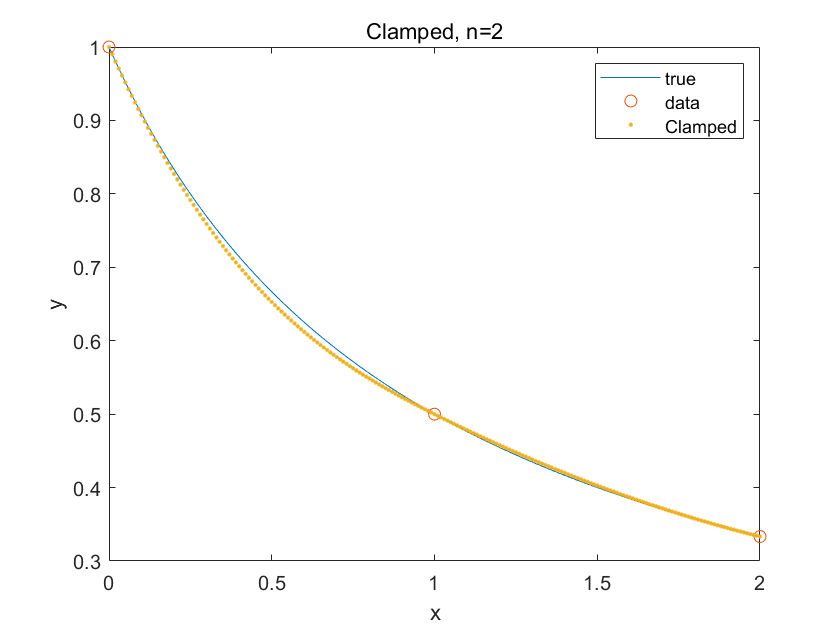

n=2;
[X_coeC2]=clam(a,b,n);
[Y2C]=plotCC(x,ut,a,b,X_coeC2,n);

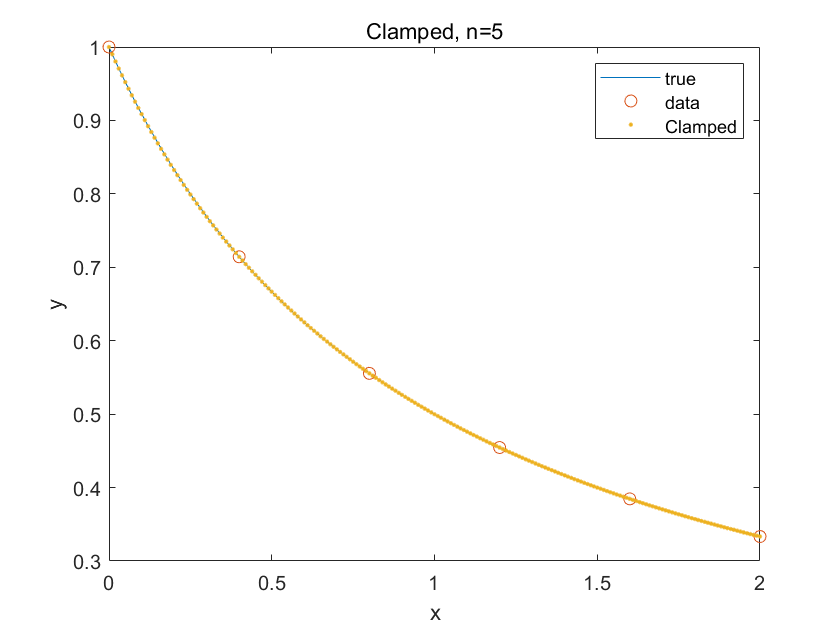


n=5;
[X_coeC5]=clam(a,b,n);
[Y5C]=plotCC(x,ut,a,b,X_coeC5,n);

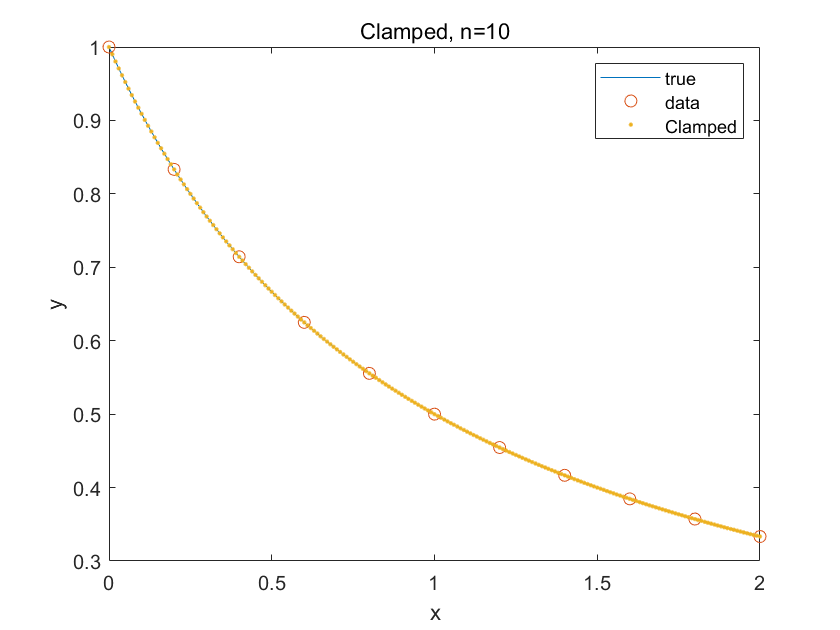


n=10;
[X_coeC10]=clam(a,b,n);
[Y10C]=plotCC(x,ut,a,b,X_coeC10,n);

from the plot we could conclude that , the more n we take the more closer two curves will be.

For natrual spline

instand (30) and (31) we will use

${{P_1 }^{\prime } }^{\prime } \left(a\right){{{=P}_1 }^{\prime } }^{\prime } \left(x_0 \right)=0$            (34)

${{P_n }^{\prime } }^{\prime } \left(a\right){{{=P}_n }^{\prime } }^{\prime } \left(x_n \right)=0$            (35)

The only things that need to be changed is

last 2 row of the matrix V

$\left\lbrack \begin{array}{ccccccccc}
0 & 0 & 2 & 6a & \cdots  & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & \cdots  & 0 & 0 & 2 & 6b
\end{array}\right\rbrack$        (36)

and last 2 terms of u becomes 0.

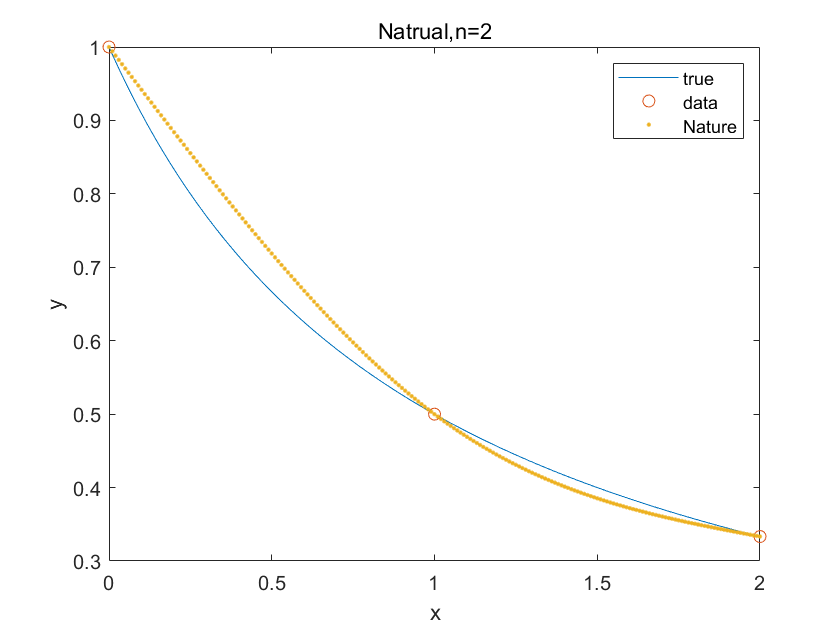

n=2;
[X_coeN2]=nat(a,b,n);
[Y2N]=plotCN(x,ut,a,b,X_coeN2,n);

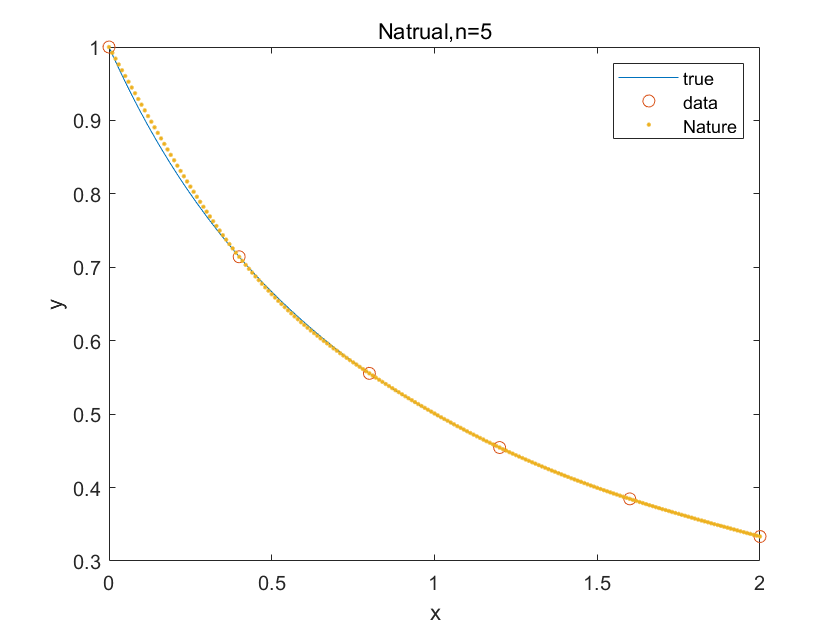


n=5;
[X_coeN5]=nat(a,b,n);
[Y5N]=plotCN(x,ut,a,b,X_coeN5,n);

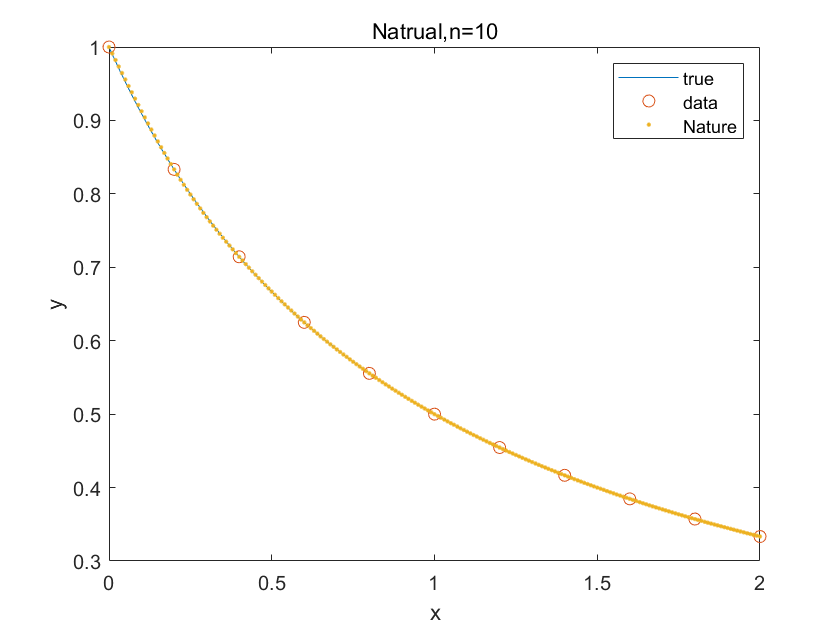


n=10;
[X_coeN10]=nat(a,b,n);
[Y10N]=plotCN(x,ut,a,b,X_coeN10,n);

we could find that when n is small the nature spline work bad compare with the clamped.

To specific compute

err_Vandermonde_n_2 = sum(abs(u_Vander_fine2V-u(xfine2V)),'all')

err_Vandermonde_n_2 = 4.5646

err_Vandermonde_n_5 = sum(abs(u_Vander_fine5V-u(xfine5V)),'all')

err_Vandermonde_n_5 = 0.0643

err_Vandermonde_n_10 = sum(abs(u_Vander_fine10V-u(xfine10V)),'all')

err_Vandermonde_n_10 = 1.3101e-04


err_Lagrange_n_2 = sum(abs(u_Lagrange2L-u(xfine2L)),'all')

err_Lagrange_n_2 = 4.5646

err_Lagrange_n_5 = sum(abs(u_Lagrange5L-u(xfine5L)),'all')

err_Lagrange_n_5 = 0.0643

err_Lagrange_n_10 = sum(abs(u_Lagrange10L-u(xfine10L)),'all')

err_Lagrange_n_10 = 1.3101e-04


err_B_spline_2=sum(abs(Y2B(:)-ut(:)),"all")

err_B_spline_2 = 0.9904

err_B_spline_5=sum(abs(Y5B(:)-ut(:)),"all")

err_B_spline_5 = 1.5040

err_B_spline_10=sum(abs(Y10B(:)-ut(:)),"all")

err_B_spline_10 = 0.0013


err_Cliamped_2=sum(abs(Y2C(:)-ut(:)),'all')

err_Cliamped_2 = 0.9904

err_Cliamped_5=sum(abs(Y5C(:)-ut(:)),'all')

err_Cliamped_5 = 0.0247

err_Cliamped_10=sum(abs(Y10C(:)-ut(:)),'all')

err_Cliamped_10 = 0.0013


err_Nature_2=sum(abs(Y2N(:)-ut(:)),'all')

err_Nature_2 = 4.5646

err_Nature_5=sum(abs(Y5N(:)-ut(:)),'all')

err_Nature_5 = 0.4788

err_Nature_10=sum(abs(Y10N(:)-ut(:)),'all')

err_Nature_10 = 0.0660

So as result, when n is high, vanermode and lagrange will has better result,

and when n is smal, B-spline and clamped will have better result.

function [X_coe]=clam(a,b,n)
%function of Clamped spline
%out put the coefficient a,b,c,d
    A=zeros(4*n,4*n);%initial Matrix V
    xx=linspace(a,b,n+1);%general grid
    x=xx(2:end);
    for i=1:n-1
        %general row 1 to n-1 of equation (27a) (32) (33)
        %general row 2 to n of equaiton (27b)
        A(i,(1+(i-1)*4:(i+1)*4))=[1 x(i) x(i)^2 x(i)^3 0 0 0 0];%(27a)
        A(i+n,(1+(i-1)*4:(i+1)*4))=[0 0 0 0 1 x(i) x(i)^2 x(i)^3];%(27b)
        A(i+n+n-1,(1+(i-1)*4:(i+1)*4))=[0 1 2*x(i) 3*x(i)^2 0 -1 -2*x(i) -3*x(i)^2];%(32)
        A(i+n+n-1+n-1,(1+(i-1)*4:(i+1)*4))=[0 0 2 6*x(i) 0 0 -2 -6*x(i)];%(33)
    end
    A(n,(1+(n-1)*4:n*4))=[1 x(n) x(n)^2 x(n)^3];%the n th row of (27a)
    A(n+n-1+n-1+n-1+1,1)=1;%the first row of (27b)
    A(n+n-1+n-1+n-1+1+1,1:4)=[0 1 2*a 3*a^2];%(30)
    A(n+n-1+n-1+n-1+1+1+1,(4*(n-1)+1:4*(n-1)+4))=[0 1 2*b 3*b^2];%(31)
    rhs=zeros(1,4*n);%initial the u vector
    s=u(x);
    rhs(1:n)=s;%(27a)
    rhs(n+1:n+n-1)=s(1:n-1);%(27b)
    rhs(n+n-1+n-1+n-1+1)=u(a);
    rhs(4*n-1)=uprim(a);%(30)
    rhs(4*n)=uprim(b);%(31)
    X_coe=A\rhs';
end

function [X_coe]=nat(a,b,n)
%function of Clamped spline
%out put the coefficient a,b,c,d
    A=zeros(4*n,4*n);
    xx=linspace(a,b,n+1);
    x=[xx(2:end)];
    for i=1:n-1
        A(i,(1+(i-1)*4:(i+1)*4))=[1 x(i) x(i)^2 x(i)^3 0 0 0 0];
        A(i+n,(1+(i-1)*4:(i+1)*4))=[0 0 0 0 1 x(i) x(i)^2 x(i)^3];
        A(i+n+n-1,(1+(i-1)*4:(i+1)*4))=[0 1 2*x(i) 3*x(i)^2 0 -1 -2*x(i) -3*x(i)^2];
        A(i+n+n-1+n-1,(1+(i-1)*4:(i+1)*4))=[0 0 2 6*x(i) 0 0 -2 -6*x(i)];
    end
    A(n,(1+(n-1)*4:n*4))=[1 x(n) x(n)^2 x(n)^3];
    A(n+n-1+n-1+n-1+1,1)=1;
    A(n+n-1+n-1+n-1+1+1,1:4)=[0 0 2 6*a];%(34)
    A(n+n-1+n-1+n-1+1+1+1,(4*(n-1)+1:4*(n-1)+4))=[0 0 2 6*b];%(35)
    rhs=zeros(1,4*n);
    s=u(x);
    rhs(1:n)=s;
    rhs(n+1:n+n-1)=s(1:n-1);
    rhs(n+n-1+n-1+n-1+1)=u(a);
    X_coe=A\rhs';
end

function [X,Y]=hua(a,b,X_coe,n)
%funtion of processing the data
%input:
%X_coe: the coefficient computed from above
%ouutput:
%X,Y: x coordinate and Y coordinate of the approximate funtion.
    h=(b-a)/n;
    dx=0.01;
    Y=[];
    X=[];
    for i=1:n
        %loop of n
        x=a+(i-1)*h:dx:a+i*h-dx;%compute each part of x coodinate
        %compute each part of y coodinate according to the coefficient
        y=X_coe(1+(i-1)*4)+ ...
        X_coe(2+(i-1)*4)*x+ ...
        X_coe(3+(i-1)*4)*x.^2+ ...
        X_coe(4+(i-1)*4)*x.^3;
        Y=[Y y];
        X=[X x];
    end
    %last point of Y
    Y=[Y X_coe(4*n-3)+X_coe(4*n-2)*b+X_coe(4*n-1)*b^2+X_coe(4*n)*b^3];
    %last point of X
    X=[X b];
end

function [datax,datay]=dian(a,b,n)
%funtion of compute the data
    datax=linspace(a,b,n+1);
    datay=u(datax);
end

function [ut]=u(x)
%function real function
    ut=1./(x+1);
end

function [up]=uprim(x)
%function of uprime
    up=-(x+1).^(-2);
end

function [bc,vv,v,t]=b_clam(a,b,n)
%function of forming the matrix, u vector and compute the alpha vector
%output
%bc:alpha vector
%vv:index of B function
%v:number of B funciton
    h=(b-a)/n;
    vv=(-4+h:h:2-h);%compute the index of B function equation(17)
    v=length(vv);%compute the number of B function
    Ab=zeros(n+3);%initial the matrix
    t=a:h:b;%define t
    for i=1:n+1
        %loop of i
        for j=1:v
            %loop of j
            Ab(i,j)=BBj(t(i),vv(j));%fill the matrix with equation(19)
        end
    end
    for j=1:v
        %fill the matrix with equation (20) and (21)
        Ab(n+2,j)=BBjprime(a,vv(j));%euqaiton(20)
        Ab(n+3,j)=BBjprime(b,vv(j));%euqaiton(21)
    end
    %general the u vector
    yb=zeros(n+3,1);
    yb(1:n+1)=u(t);%fill the first n+1 terms with u(t)
    yb(n+2)=uprim(a);%euqaiton(20)
    yb(n+3)=uprim(b);%euqaiton(21)
    bc=Ab\yb;%compute the alpha vector
end

function [Bt1]=B1(t)
%equation (13)
    Bt1=1/6*t.^3;
end

function [Bt2]=B2(t)
%equation (14)
    Bt2=1/6*(-3*(t-1).^3+3*(t-1).^2+3*(t-1)+1);
end

function [Bt3]=B3(t)
%equation (15)
    Bt3=1/6*(3*(t-2).^3-6*(t-2).^2+4);
end

function [Bt4]=B4(t)
%equation (16)
    Bt4=1/6*(-(t-3).^3+3*(t-3).^2-3*(t-3)+1);
end

function [Bt1p]=B1prime(t)
%equation (22)
    Bt1p=1/2*t.^2;
end

function [Bt2p]=B2prime(t)
%equation (23)
    Bt2p=1/6*(-9*(t-1).^2+6*(t-1)+3);
end

function [Bt3p]=B3prime(t)
%equation (24)
    Bt3p=1/6*(9*(t-2).^2-12*(t-2));
end

function [Bt4p]=B4prime(t)
%equation (25)
    Bt4p=1/6*(-3*(t-3).^2+6*(t-3)-3);
end

function [k]=BBj(t,j)
%function of combina B1, B2, B3, B4 together
%j means the shifts take placed on B
    if j<=t && t<=j+1
        k=B1(t-j);
    elseif j+1<=t && t<=j+2
        k=B2(t-j);
    elseif j+2<=t && t<=j+3
        k=B3(t-j);
    elseif j+3<=t && t<=j+4
        k=B4(t-j);
    elseif t>=j+4 || t<=j
        k=0;       
    end
end

function [k]=BBjprime(t,j)
%function of combina B1prime, B2prime, B3prime, B4prime together
%j means the shifts take placed on Bprime
    if j<=t && t<=j+1
        k=B1prime(t-j);
    elseif j+1<=t && t<=j+2
        k=B2prime(t-j);
    elseif j+2<=t && t<=j+3
        k=B3prime(t-j);
    elseif j+3<=t && t<=j+4
        k=B4prime(t-j);
    elseif t>=j+4 || t<=j
        k=0;       
    end
end

function [Y]=plotCC(x,ut,a,b,X_coe,n)
%funtion of plot clamped spline
%out put the approximate y value
    [X,Y]=hua(a,b,X_coe,n);%compute the y coordinate
    [datax,datay]=dian(a,b,n);%input the data
    plot(x,ut)%real value
    hold on
    plot(datax,datay,'o')%data
    plot(X,Y,'.')%Clamped
    xlabel('x');ylabel('y')
    legend('true','data','Clamped')
    title(['Clamped, n=',num2str(n)])
    hold off
end

function [Y]=plotCN(x,ut,a,b,X_coe,n)
%funtion of plot nature spline
%out put the approximate y value
    [X,Y]=hua(a,b,X_coe,n);
    [datax,datay]=dian(a,b,n);
    plot(x,ut)
    hold on
    plot(datax,datay,'o')
    plot(X,Y,'.')
    xlabel('x');ylabel('y')
    legend('true','data','Nature')
    title(['Natrual,n=',num2str(n)])
    hold off
end

function [Y]=plotB(bc,vv,v,x,ut,n,t)
%funtion of ploting the B-spline
%input:
%bc:alpha vector
%vv:index of B function
%v:number of B funciton
%x:grid
%ut:real value
%yb:u vector
%n
    num=length(x);
    Y=zeros(num,1);
    for i=1:v
        for j=1:num
            %compute the linear compbination from equation (18)
            Y(j)=Y(j)+bc(i)*BBj(x(j),vv(i));
        end
    end    
    plot(x,ut,'k', 'LineWidth',2)%true value
    hold on
    plot(x,Y,'.')%approximate value
    plot(t,u(t),'.','MarkerSize', 30)%data
    xlabel('x');ylabel('y')
    legend('true','B-spline','data')
    title(['B-spline n=',num2str(n)])
    hold off
end

function [x,y,xfine,u_Vander_fine,a_vec]=van(a,b,n)
%function of computing the Vandermonde martix and correspounding
%coefficients
%take input a,b,and n
%out put x: the x coodinate of data point according to n
%out put y: the y coodinate of data point that compute from x
%xfine: a finer grid of x
%u_Vander_fine: approximate the polynomial using the coefficient compute from V and y
%a_vec: vector a
    h = (b-a)/n; 
    x = a + (0:n)*h; % define the x values
    y = u(x); % define the corresponding y values as y_j = u(x_j)
    Vmat = zeros(length(x));
    for ii=1:length(x)
        % loop over the data points
        for jj=1:length(x) 
            % loop over the columns of the Vandermonde martix
            Vmat(ii,jj) = x(ii)^(jj-1); 
            % since matlab indices starts at 1, so we need to subtract 1
        end
    end
    rr_form     = rref([Vmat,y(:)]);
    a_vec       = rr_form(:,end); % peeling off the last column
    xfine         = a:0.01:b;%define a finer grid x
    u_Vander_fine = a_vec(1)*ones(size(xfine));
    for jj=1:n
        %compute the polynomial from vector a
        u_Vander_fine = u_Vander_fine + a_vec(jj+1)*xfine.^(jj);
    end
end

function [x,y,xfine,u_Lagrange]=lan(a,b,n)
%function of compute the Lagrange fomular
%input a, b and n
%outpout
%out put x: the x coodinate of data point according to n
%out put y: the y coodinate of data point that compute from x
%xfine: a finer grid of x
%u_Lagrange:  approximate the polynomial 
% using the coefficient compute Lagrange fomular
    h = (b-a)/n;
    x = a + (0:n)*h; % define the x values
    y = u(x); % define the corresponding y values as y_j = u(x_j)
    N          = length(x);
    xfine       = a:0.01:b; % define the finer x values
    u_Lagrange  = zeros(size(xfine));
    for k = 1:N
        %loop each k from equation (6)
        w = ones(size(xfine));
        for j = [1:k-1 k+1:N] % This loop the index from equation (8)
            w = (xfine-x(j))./(x(k)-x(j)).*w;
        end
        u_Lagrange = u_Lagrange + w*y(k); 
        % This adds up each y_k*l_k(x) term, equation (7)
    end
end

function []=plotA(x,y,xfine,u_Vander_fine,n)
%function of plot the polynomial from Vandermonde martix
%take input:
%x: the x coodinate of data point according to n
%y: the y coodinate of data point that compute from x
%xfine: a finer grid of x
%u_Vander_fine: approximate the polynomial using the coefficient compute from V and y
%n
    plot(x,y,'.','MarkerSize', 30)%plot the data
    hold on;
    plot(xfine,u(xfine),'k', 'LineWidth',2)%plot the true value
    plot(xfine, u_Vander_fine, 'r')%plot the polynomial
    xlabel('x');ylabel('y');
    legend('Data','u', 'Vander poly')
    title(['Plot of Polynomial interpolation using ' ...
        'Vandermonde Matrix for u=1/(1+x),n=',num2str(n)])
    hold off
end

function []=plotAN(x,y,xfine,u_Lagrange,n)
%function of plot the polynomial from Lagrange fomular
%take input:
%x: the x coodinate of data point according to n
%y: the y coodinate of data point that compute from x
%xfine: a finer grid of x
%u_Lagrange: approximate the polynomial using the coefficient compute Lagrange
%n
    plot(x,y,'.','MarkerSize',30);%plot the data
    hold on;
    plot(xfine,u(xfine),'k', 'LineWidth',2);%plot the true value
    plot(xfine,u_Lagrange,'-.r','LineWidth',1)%plot the polynomial
    xlabel('x');ylabel('y');
    legend('Data','u','Lagrange function')
    title(['Plot of Polynomial interpolation using' ...
        ' Lagrange Matrix for u=1/(1+x),n=',num2str(n)])
    hold off
end
